# Decode Brain Waves using Machine Learning

## Learning Objectives

In this activity, students will:

- **Understand the basics of EEG signals** and how they can indicate whether eyes are open or closed.

- **Learn what features are** in data and how feature extraction (like signal strength) helps classify EEG patterns.

- **Explore how machine learning works** by training a computer to recognize patterns in EEG data using the k-nearest neighbor algorithm.

- **Practice building and testing a simple machine learning model** to classify EEG data automatically.

- **Evaluate and compare **the accuracy and efficiency of human labeling vs. computer predictions.

## **Instructions**

- Open the Live Script titled: "EEG_Classification_Activity.mlx".

- Review introductory material on EEG data

- Instruct students to complete the [activity handout](matlab:open('../Decode Brain Waves with Machine Learning/EEGClassification_Activity_Handout.pdf')) ("EEG_Classification_Activity_Handout.pdf") and practice classifying EEG signals by hand (Part 1). Once students have completed the activity, have students pair up or group up to discuss similarities or differences in how they classified the EEG signals.

- Guide students through Parts 2 and 3. Students will practice building, testing, and evaluating a simple machine learning model to classify EEG data in MATLAB.

- Guide students through the discussion (Part 4) to compare and contrast human labeling versus machine learning classification.

## **Introduction**

**EEG**, or electroencephalography, is a way to measure the tiny electrical signals in your brain using special sensors placed on your head. These signals look like wavy lines, and scientists study the patterns to learn what your brain is doing. One cool thing EEG can show is whether your eyes are open or closed. When your eyes are closed and you’re relaxed, your brain makes more “alpha waves,” which are slow and smooth. When your eyes are open, those alpha waves get smaller, and faster waves called “beta waves” show up more.

**What’s the difference?** Alpha waves have a lower frequency, meaning they move up and down fewer times per second—kind of like gentle ocean waves. Beta waves have a higher frequency, so they wiggle much faster, like ripples in a pond when you throw a stone. Alpha waves also tend to have a higher amplitude, which means their “hills and valleys” are taller, while beta waves have a lower amplitude, so their wiggles are smaller. Scientists use these differences in speed and size to figure out what your brain is doing at any moment!

Take a look at the example EEG data below. A subject with EEG sensors on their head repeatedly opened and closed their eyes for a period of several minutes. How does the EEG signal differ between periods of time when the subject's eyes are open versus closed?

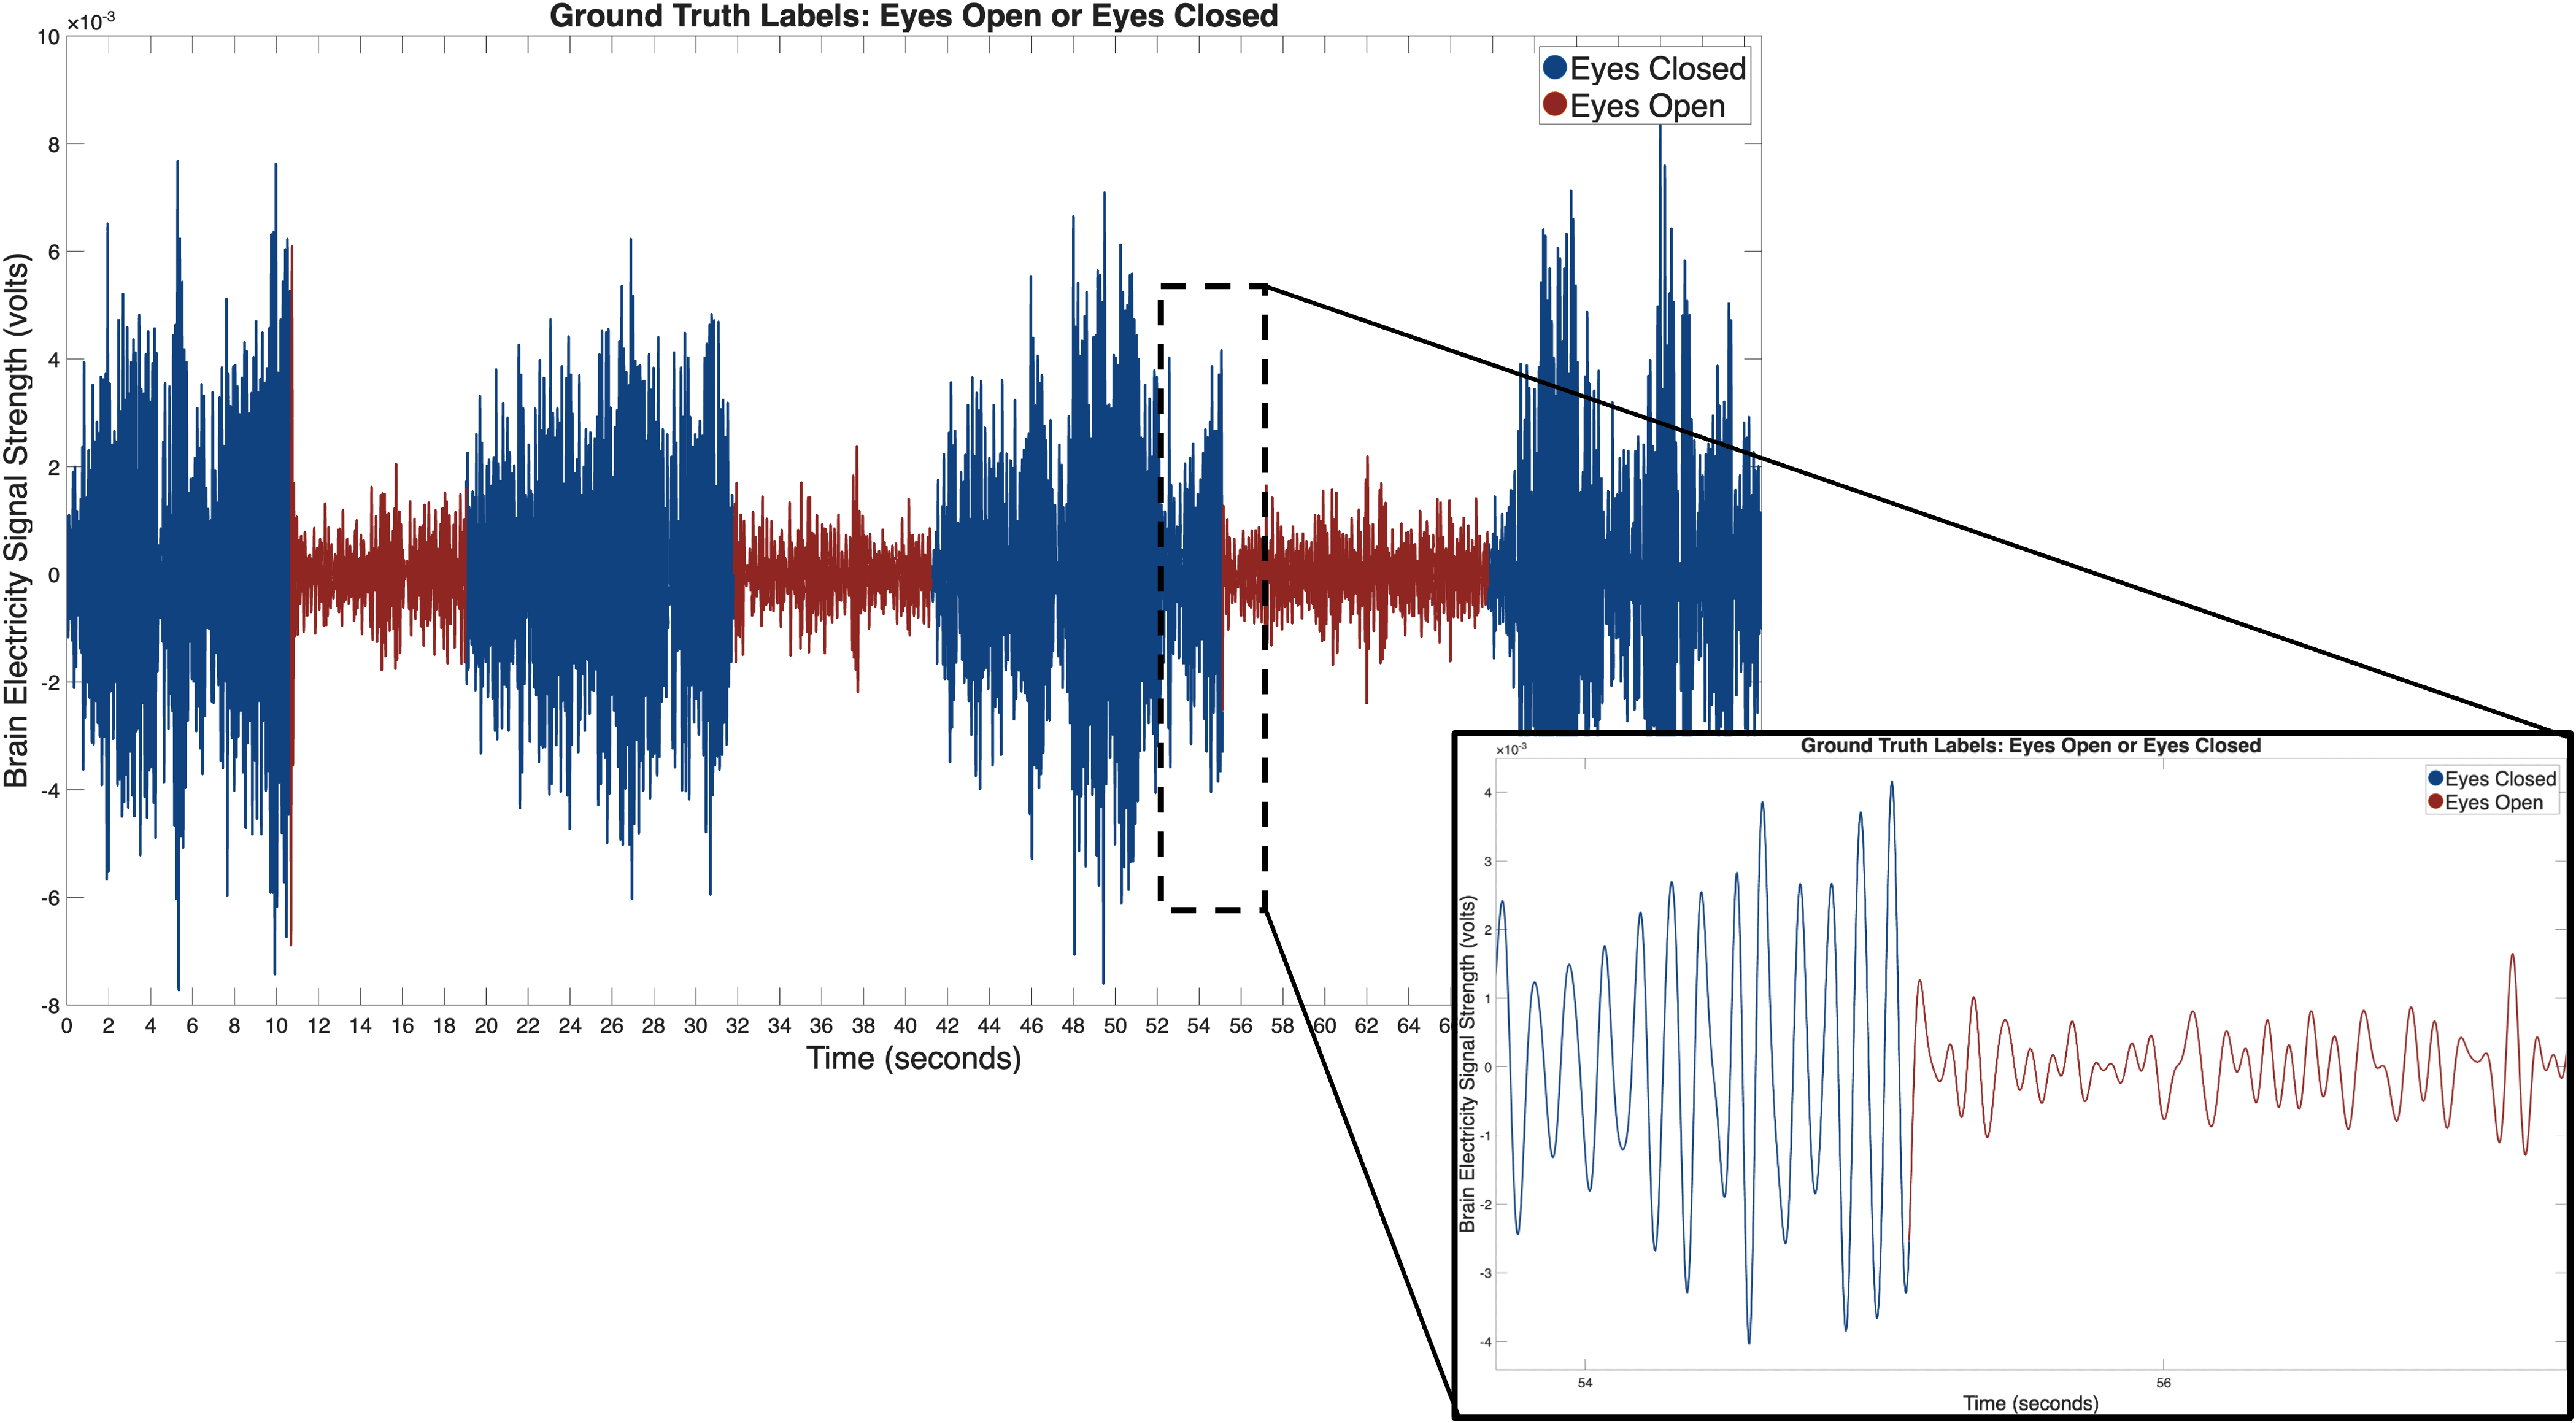

## Part 1: Decode EEG Data by Hand

Now that you have an understanding of what the EEG signal looks like when a person's eyes are open versus closed, let's practice classifying the data by completing [this activity](matlab:open('../Decode Brain Waves with Machine Learning/EEGClassification_Activity_Handout.pdf')). You will use different colored markers to label the periods of time where you think the subject's eyes were open versus closed. Remember that *stronger* (or higher amplitude) brain electricity signals likely means that the subject's eyes were closed during that time period and that *weaker* (or smaller amplitude) brain electricity signals likely means that the subject's eye were open. Return to this document when you have completed the activity.

**Handout Preview**:

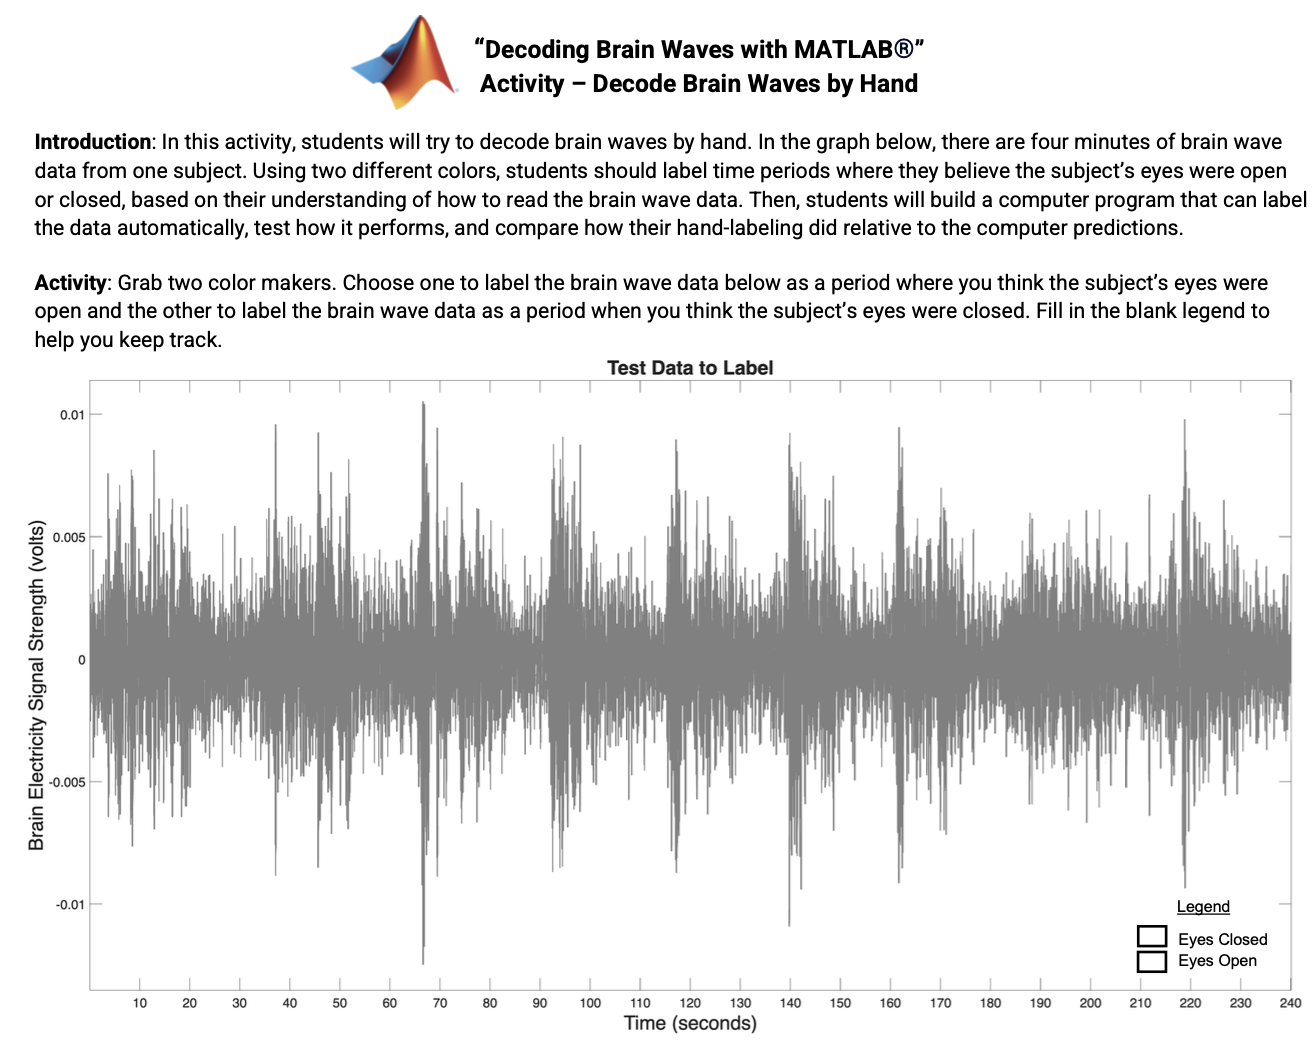

## Part 2: Build a Computer Program that can Decode Brain Waves

In the activity handout, you were given a set of brain wave data (EEG data) where the subject opened and closed their eyes repeatedly. You were asked to label the data by hand to identify the periods of time when you through the subject had their eyes open or closed, using the strength of the brain electricity signal to decide how to label the data.  

You probably found it boring, difficult, and time-consuming to label all that data by hand! Luckily, we can build computer programs that can do this work for us automatically - saving a lot of time. But, how do we know that a computer can do this more accurately than a human doing it by hand? Let's find out!

Now, using MATLAB, you will first be guided through building a computer program that can automatically label any set of brain wave data we give it, using a process called **machine learning**. Machine learning is a type of **artificial intelligence**, or AI. Then, we'll compare the labels that computer assigned to the data and compare it to the labels you assigned by hand. That will let us figure out how much better or worse the computer did than our own handiwork!

The following sections explain all the steps that go into building the computer program, and includes the computer code that performs each step. To build the computer program in MATLAB, click the button 'Run Section'. To see the code underlying each step, you can toggle between views using the toolbar on the right hand side:

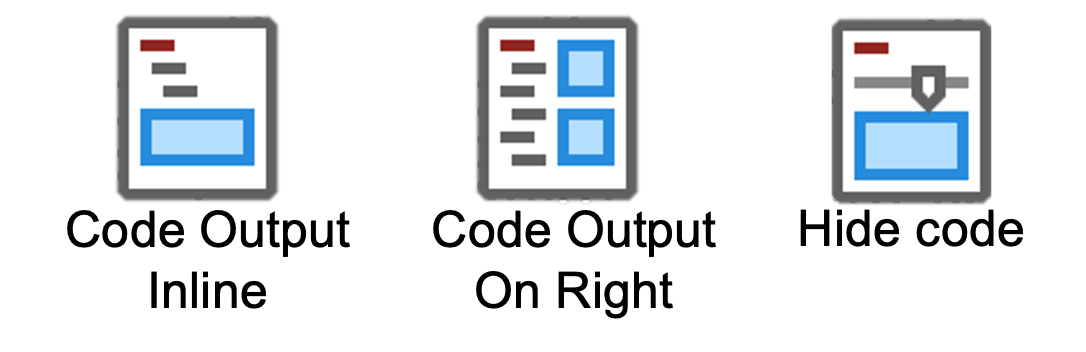

1. The first thing we need to do is give all the brain wave data to the computer. We have brain wave data from four subjects that we'll use to build and test our computer program. Hit 'Run Section'.

 
EEG_data = load('EEG_data.mat'); 
signalData = EEG_data.signalData;

2. We are going to have the computer label the data the same way that you did in the class activity. You labeled each second of the brain wave data as a period of time in which the subject's eyes were open or closed. So, next, we're going to organize all of the brain wave data into one-second chunks of time. Hit 'Run Section'.

 
% Split the brain wave data into one-second chunks of time
signalDataSplitted = {};
sizeOfChunks = 10000;

for i = 1: length(signalData)
    signalToSplit = signalData{i};

    % Shorten data so that it is divisible by sizeOfChunks
    remainder = rem(width(signalToSplit), sizeOfChunks);
    signalToSplit = signalToSplit(1:end-remainder);
    
    % Reshape data into proper size format
    signalToSplit = reshape(signalToSplit, sizeOfChunks, width(signalToSplit)/sizeOfChunks)';
    
    % Combine data from different subjects together
    signalDataSplitted = [signalDataSplitted ; mat2cell(signalToSplit, ones(size(signalToSplit,1), 1))];    
end

signalDataSplitted = signalDataSplitted(2:end); % Get rid of the first second, which doesn't actually have real data in it

3. For the set of brain wave data we are working with, someone has actually already labeled every second of the data based on observing whether the subject's eyes were opened or closed. This represents the **ground truth** - we *know* for sure that the subject's eyes were open or closed because we actually observed the subject during the experiment. Let's match up these ground truth labels with every second of the brain wave data. Hit 'Run Section'.

 
% Organize the ground truth labels to match the one-second chunks of time
% we split the brain wave data into.
responseData = EEG_data.responseData;
responseDataSplitted = {};

for i = 1: length(signalData)
    responseToSplit = responseData{i};

    % Shorten data so that it is divisible by sizeOfChunks
    remainder = rem(width(responseToSplit), sizeOfChunks);
    responseToSplit = responseToSplit(1:end-remainder);
    
    % Reshape data into proper size format
    responseToSplit = reshape(responseToSplit, sizeOfChunks, width(responseToSplit)/sizeOfChunks)';
    
    % Combine data from different subjects together
    responseDataSplitted = [responseDataSplitted ; mat2cell(responseToSplit, ones(size(responseToSplit,1), 1))];    
end

responseDataSplitted = responseDataSplitted(2:end); % Get rid of the first second, which doesn't actually have real data in it

labelsEachSecond = [];
for i = 1: length(signalDataSplitted)
    labelsEachSecond = [labelsEachSecond ; categorical(mode(responseDataSplitted{i}))]; 
end

4. Phew - we've finished loading in all the data and organizing it. Now, we can get to building the brain wave decoder! 

First up, we need to define the **features** of the data that help us categorize it into 'eyes closed' or 'eyes open'. Imagine that you have a set of images that contain either cars or cats. The biggest clue that an image belongs in the car category is probably whether or not you can see a car in the image and the biggest clue that an image belongs in the cat category is probably whether or not you see a cat in the image. Whether a car or a cat is in the image are the key **features** of the data that help you classify the images.

For our brain wave data, we learned that when the brain wave signal is strong, or the waves are bigger, the eyes are likely to be closed. When the brain wave signal is weak, or the waves are smaller, the eyes are likely to be open. So, the key feature of the brain wave data that lets us classify it into 'eyes closed'  or 'eyes open' is the strength and size of the brain waves. When you labeled the data yourself by hand, you used that feature to make decisions about how to label each one-second chunk of time. We need to tell the computer to also use that same feature to make its decisions about the labeling the data. This step in building the computer program is called **feature extraction**. Hit 'Run Section'.

 
% Perform feature extraction on the brain wave data - this code is going to
% take each second of the brain wave data and define whether or not the
% brain wave signal was strong or weak during that second
for i = 1 : length(signalDataSplitted)
    L = length(signalDataSplitted{i});
    signalDataSplitted{i} = fft(signalDataSplitted{i});
    P2 = abs(signalDataSplitted{i}/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    signalDataSplitted{i} = P1;
end
signalDataSplitted = cell2mat(signalDataSplitted);

5. Now that we've told the computer program *what *feature to use when making its decision to categorize our brain wave data, we have to teach it *how to make the decision*. In other words, we need to train the computer program to recognize that when the brain signal is strong, it should categorize that one-second chunk as a period when the subject's eyes were closed. And if the brain signal is weak, it should categorize it as a period when the subject's eyes were open. This process is called **training the model**.

To train our model, first we'll split our data into 'training data' and 'testing data'. The 'training data' is the brain wave data we'll use to teach the computer program how to classify the brain signals. After we've trained the model, we'll test how the computer program performs with the 'testing data'. Hit 'Run Section'.

 
% Here, we're splitting the data into two sets - one set of training data
% and one set of testing data. We'll use about 70% of our whole data set to
% train the model.

signalDataTraining = signalDataSplitted(1:1200,:);
labelsTraining = labelsEachSecond(1:1200,:);
signalDataTesting = signalDataSplitted(1201:end,:);
labelsTesting = labelsEachSecond(1201:end,:);

Let's get to teaching the computer how to make decisions based on the features of the data! There are a lot of ways we could teach the computer how to make decisions about categorizing data - all these different ways are called **machine learning algorithms**. An algorithm is a step-by-step set of instructions to solve a problem or complete a task (like a recipe!) 

For this activity, we're going to use a machine learning algorithm that's called the **k-nearest neighbor algorithm**. To explain how this works, let's go back to the example of classifying images as either images of cars or images of cats. What if there are images that contain both cars and cats? How would you classify the images then? Take a look at this graph:

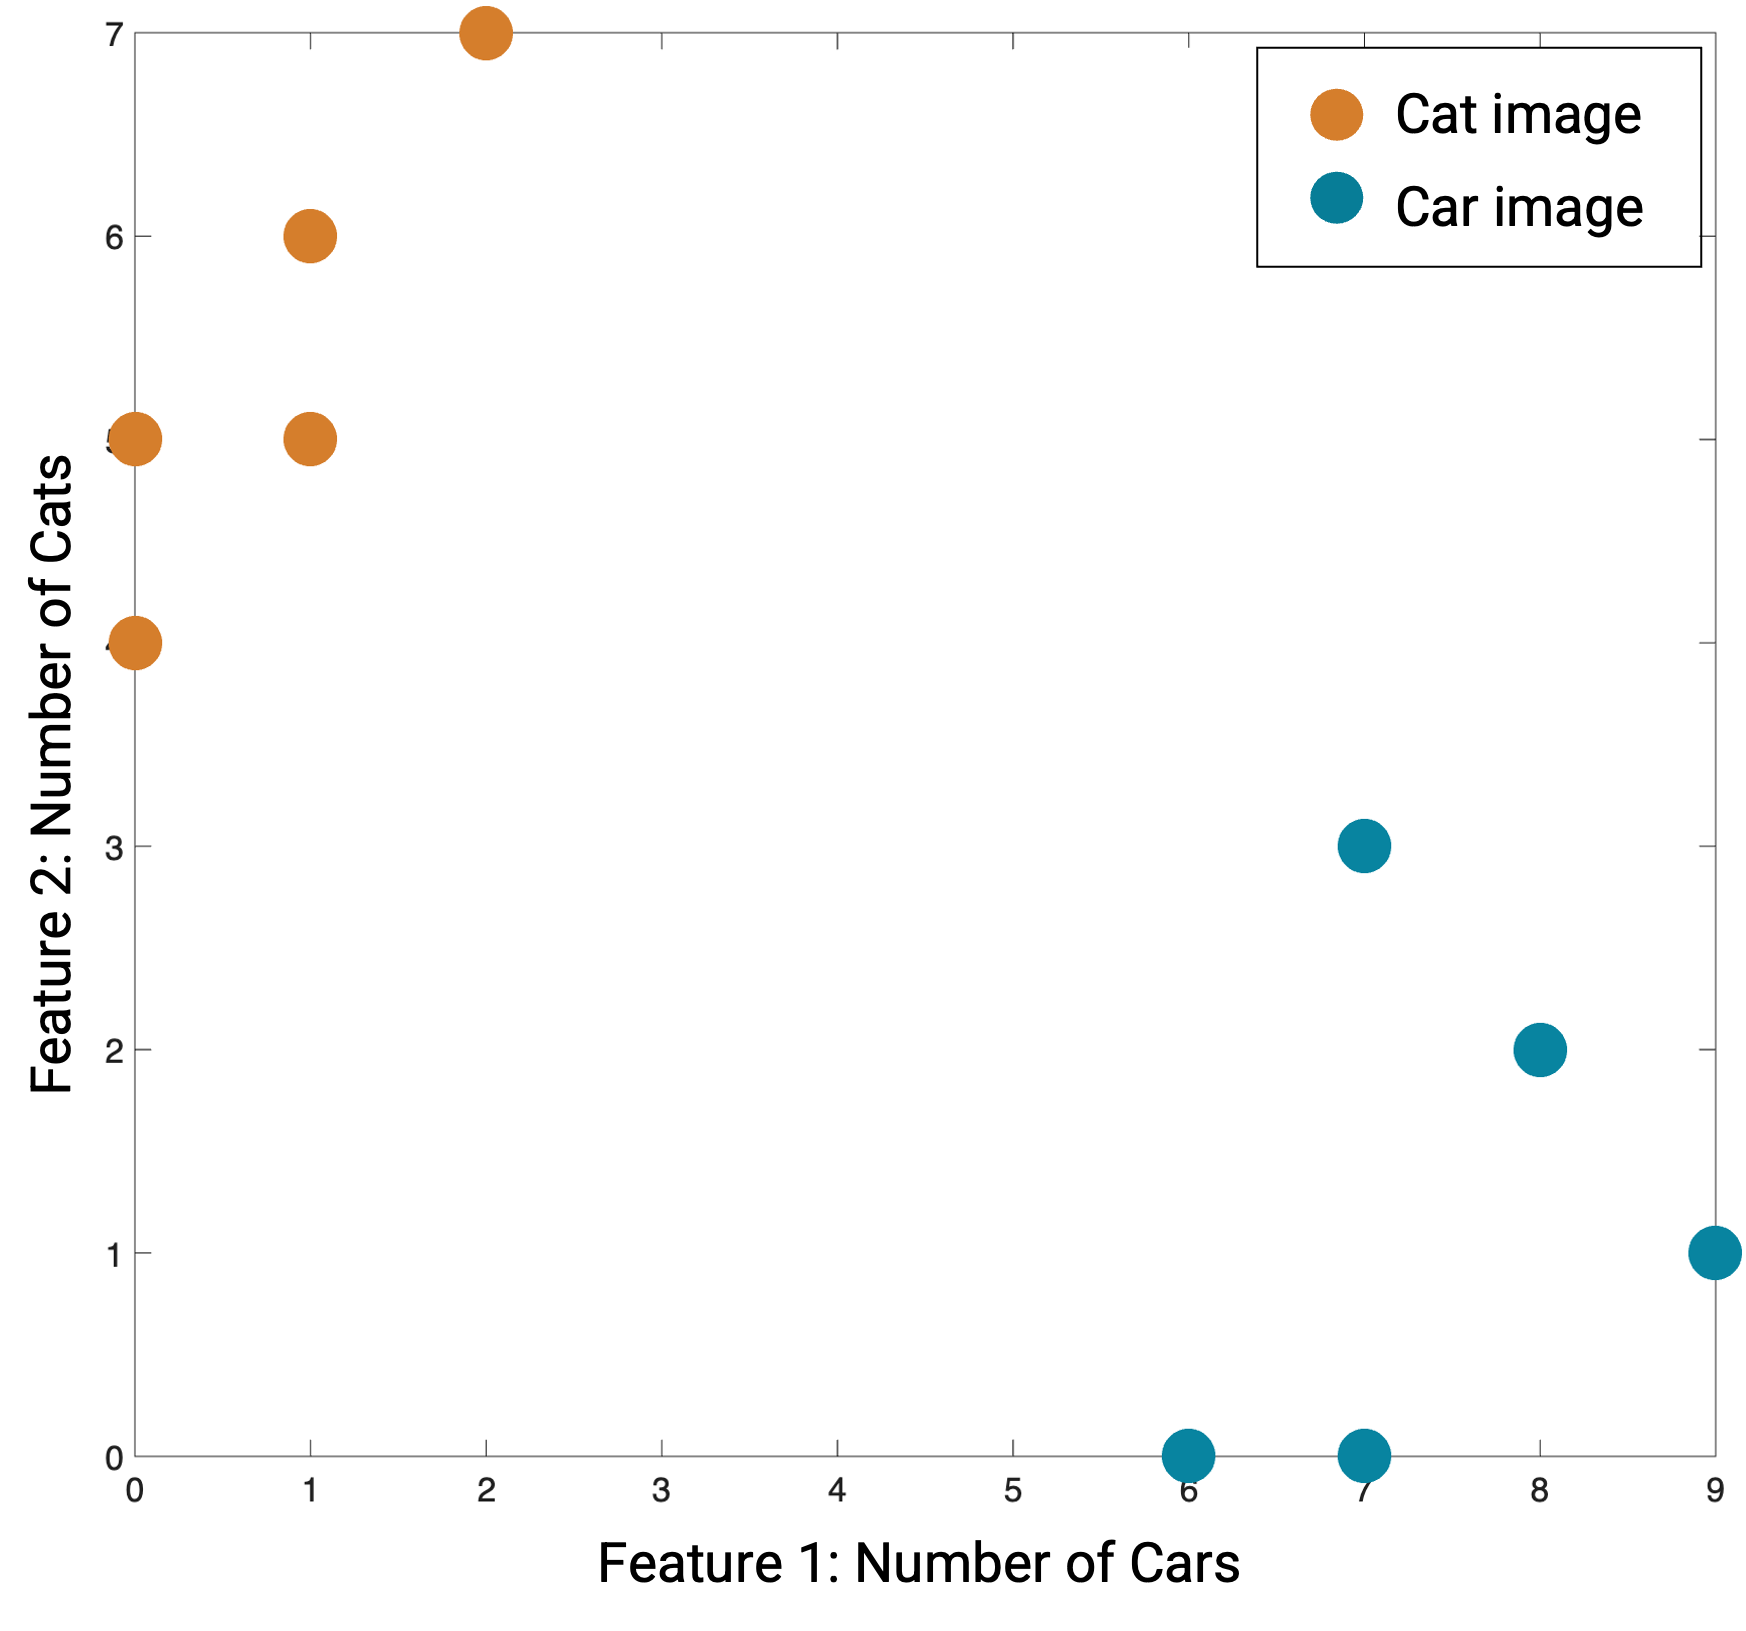

Remember that the key features you likely use to classify whether an image is a car image or a cat image is whether there are cars or cats in the images. These are set as 'Feature 1' on the x-axis and 'Feature 2' on the y-axis. Looking at the graph, we can see that images with a lot of cars in them but not many cats are classified as car images. And likewise, images with a lot of cats but not many cars are classified as cat images. Imagine we see a new image, and we extract those two features from it - counting the number of cars and number of cats in the image. In our new image, there were 5 cars and 3 cats. Let's plot that new image on our graph:

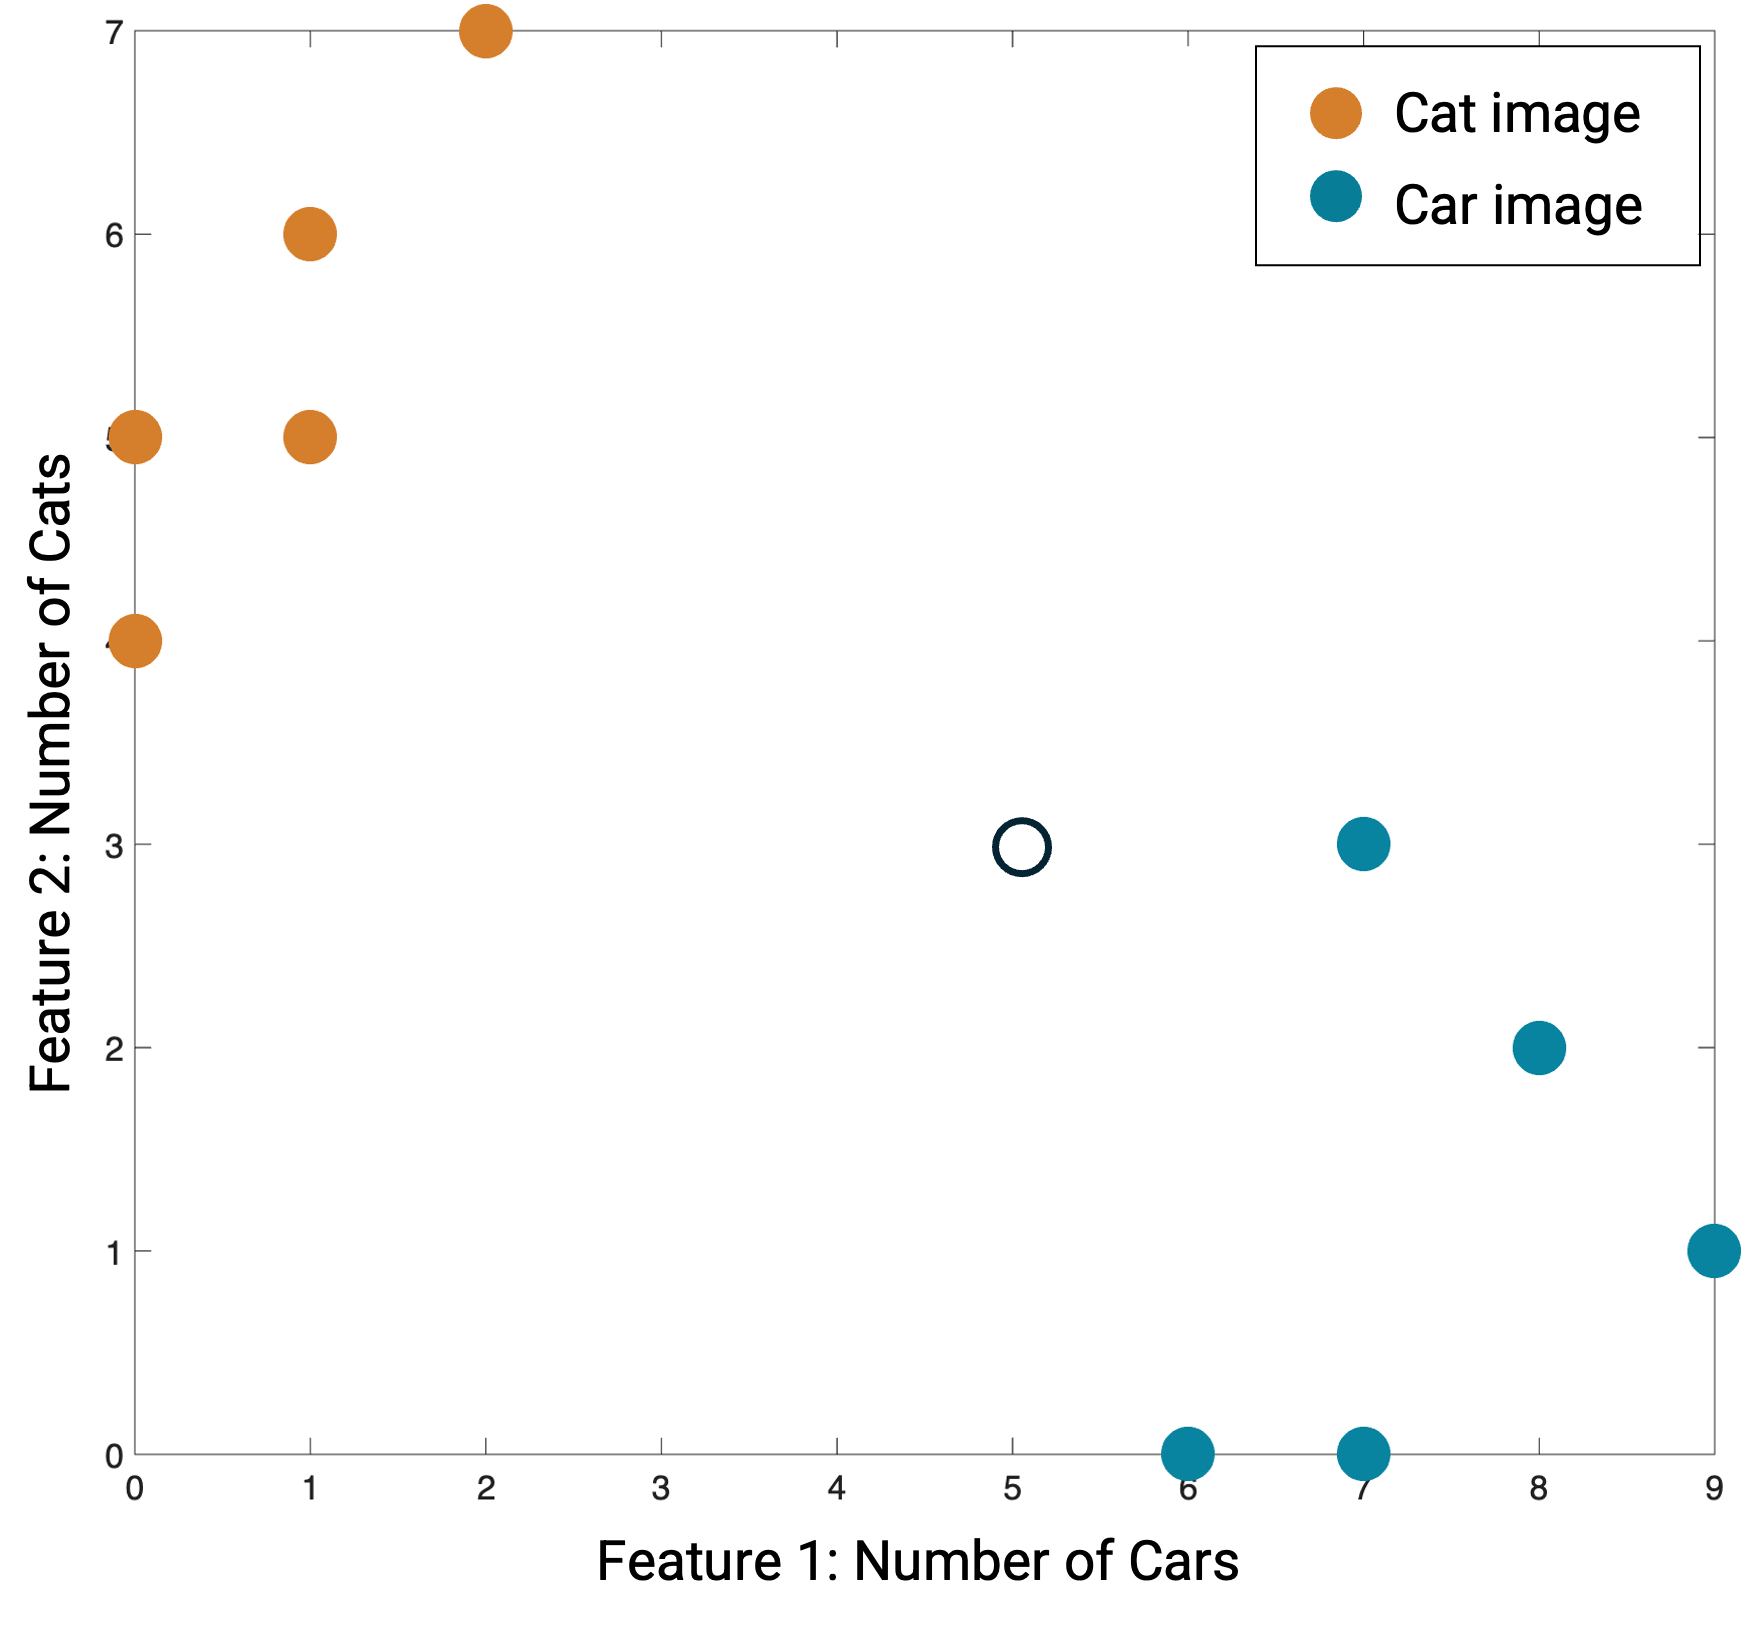

If the computer is using the **k-nearest neighbor algorithm** to make a decision about how to classify this new image, the computer will measure how close this image is on the graph to other images that were classified as car images compared to cat images. In other words, it will look for the new image's *nearest neighbors* on the feature graph.

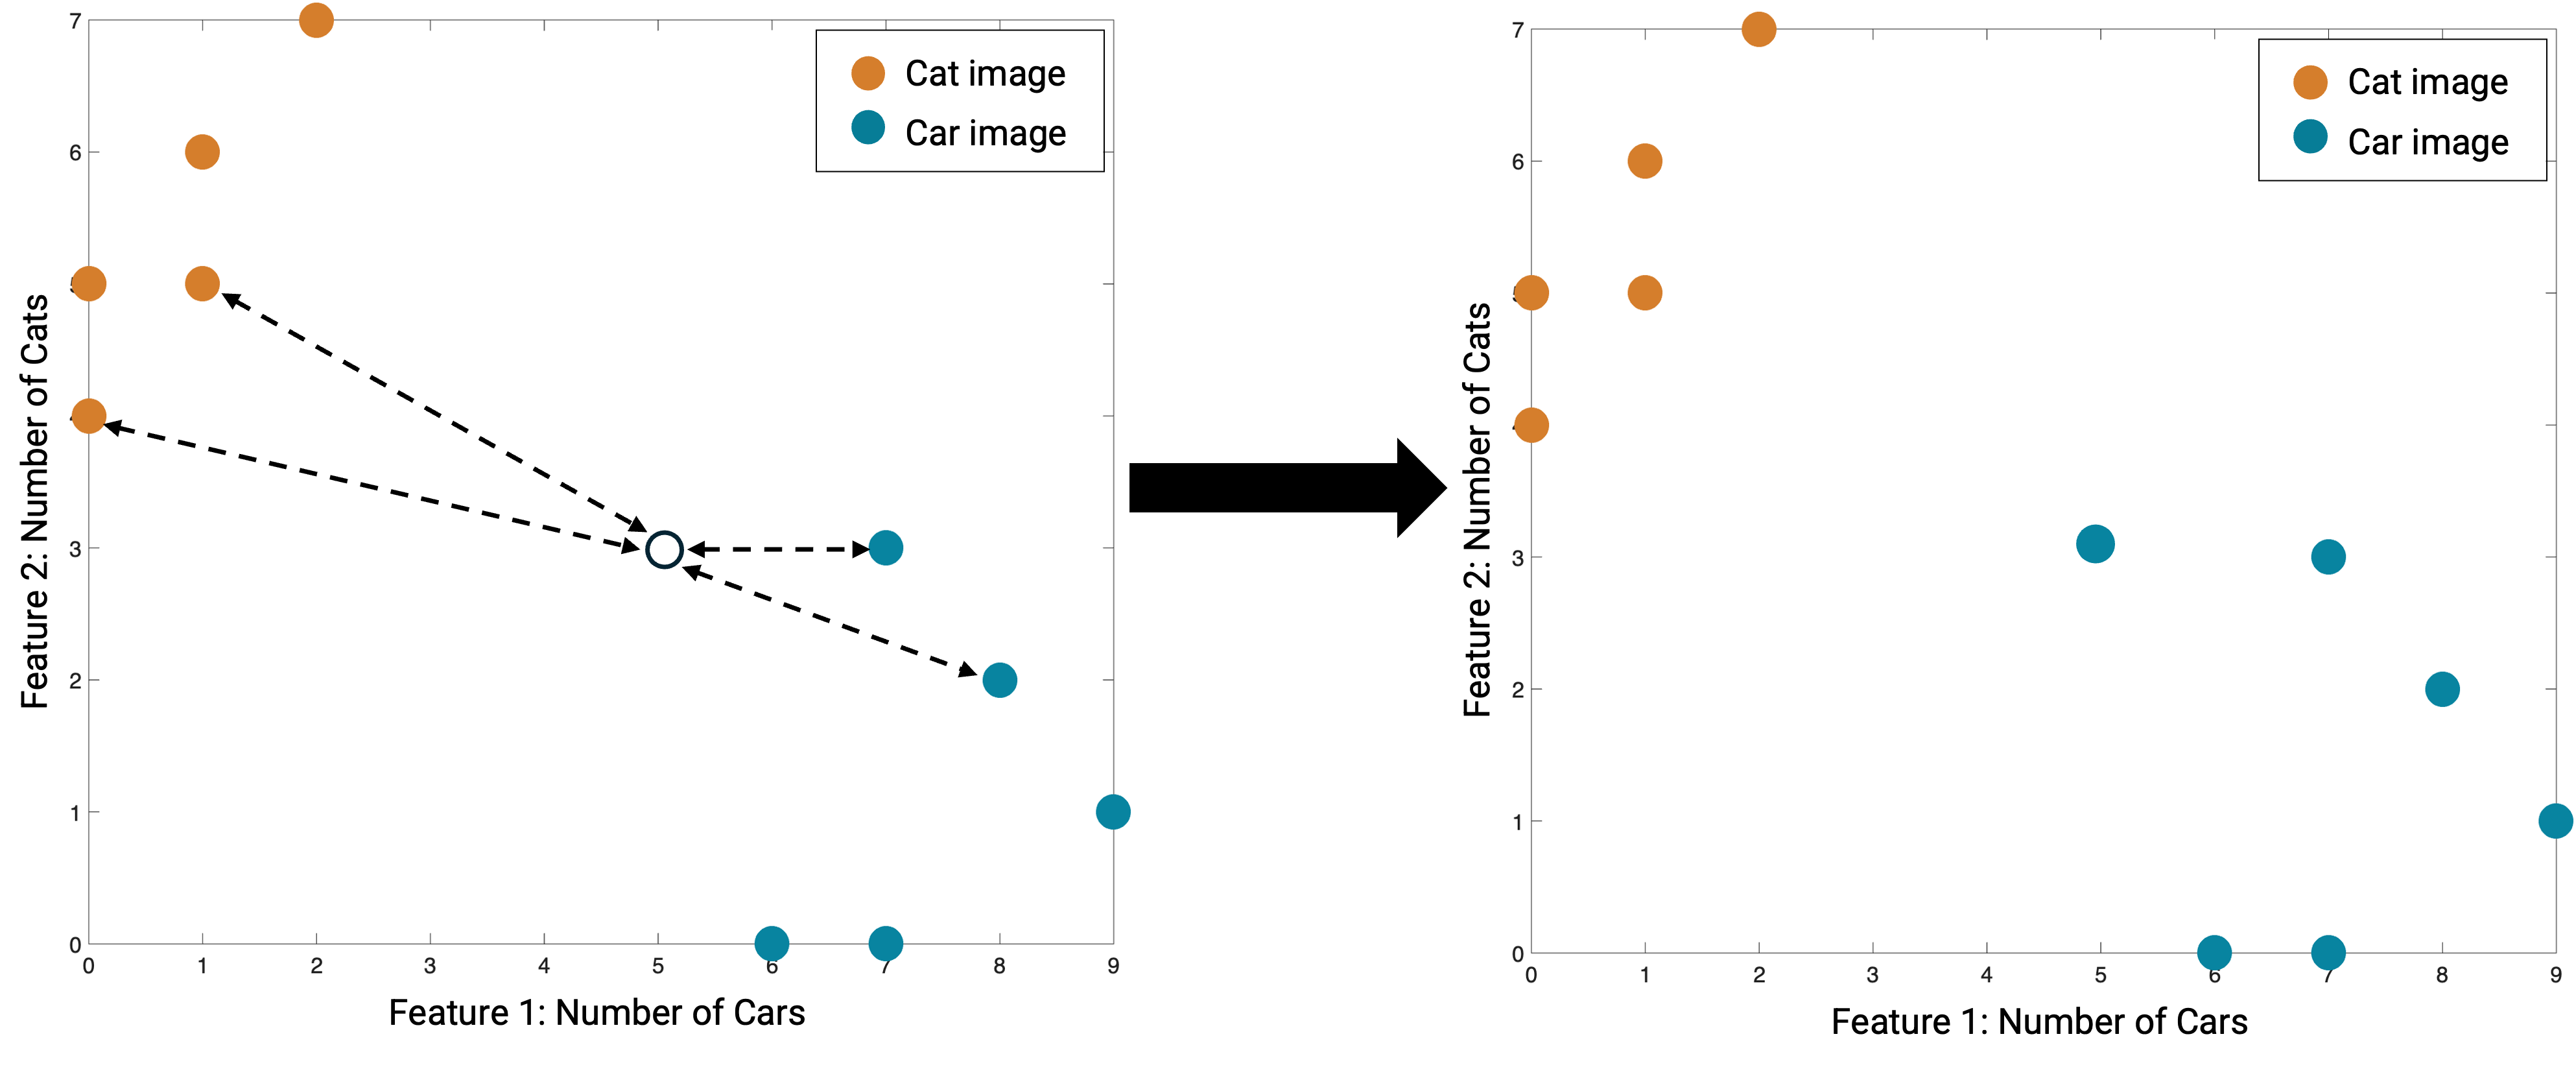

The computer will give the new image the same label as the one its nearest neighbors have. In this case, the new image's neareast neighbors (the points on the graph closest to it) were labeled as car images. So, what this algorithm dictates the computer should do is label this new image as a......... car image! And, that makes sense because the new image has more cars in it than cats. 

Now that we have a better idea of what the k-nearest neighbor algorithm is, let's think about how it applies to our brain wave data. Remember - what's the critical feature of the brain wave data that we'll ask the computer to use to make a decision about the label?

That's right - we are using the** strength of the brain signal**, or how big the brain waves are, to decide whether the subject's eyes were open or closed during that one-second chunk of time. And we're telling the computer to follow the steps in k-nearest neighbor recipe (algorithm!) to make a decision about the label. So we're telling the computer *what* *information* to use to make its decision and *what steps* it should take to make its decision.

This whole algorithm business seems like it would be difficult to use, right? Lucky for us, MATLAB has a lot of built-in functions to train the computer automatically. All we have to do is give MATLAB our training data and tell it what algorithm we want the computer to use - in this case, the k-nearest neighbor algorithm. 

One important thing to note, when we train the computer to do this task, we are giving it the brain wave data *and* the ground truth labels as part of the training dataset. That's because we want the computer to compare its decisions to the 'right answers', the ground truth labels. That way, the computer can learn from its mistakes as it's training. It's like how you do your math homework to practice solving math problems, and you get better when you see what questions you got right and what questions you got wrong. You can learn from what you did wrong, and use that to do better on your math test! 

And, we* are* going to test the computer after we train it. That's what the 'testing' data is for :)

6. OK - let's train our computer! Hit 'Run Section'.

 
% This MATLAB function trains the computer to use the k-nearest neighbor
% algorithm to make decisions about labeling the data. Here, we're
% specifying that the computer should make its decision using the labels of
% the 13 neighbors nearest to any new piece of data.
Mdl = fitcknn(signalDataTraining, labelsTraining,'NumNeighbors',13);

Aaaaaaand that's it! With that one line of code, we've trained our model. Congratulations - you have now finished building computer program that can decode brain waves!

## Part 3: How Well did the Computer Program Decode the Brain Waves?

To see how well the compute program can decode our brain wave date, we'll give it the other subset of our dataset - the 'testing data' (the other ~30% of the dataset) ask it to predict whether the subject's eyes were open or closed for every one-second chunk of data.

After it's made its predictions, we'll evaluate the program's performance by creating a **confusion matrix** to compare the program's prediction with the ground truth labels we have for the testing data. **A confusion matrix** is a table that shows how well a computer made predictions compared to the correct answers. It tells you how many times the computer was **right** and how many times it was **wrong** for each category. For example, if the computer is guessing whether eyes are open or closed, the confusion matrix shows how many “open” guesses were correct and how many were mistakes, and the same for “closed.” It’s like a scorecard for the computer’s predictions! Think of a confusion matrix like a rubric that we use to grade the computer program's performance, just like how your teacher would use a rubric to grade a homework assignment you turned in.

When you're ready to put our computer program to the test, hit the "Run Section" button again.

 
% These lines of code are asking the computer program to predict whether
% the subject's eyes were open or closed using the brain wave data from the
% 'testing' set.
predictions = [];
for idx = 1:height(labelsTesting)
    predictedLabel = predict(Mdl, signalDataTesting(idx,:));
    labelsPredict(idx) = double(predictedLabel);
end

% These lines of code then evaluate how well the computer program performed
% by creating a confusion matrix to compare the computer predictions about the data
% with the ground truth labels.
labelsTestingNamed = categorical(labelsTesting,categorical([3,4]),{'opened','closed'});
labelsPredictNamed = categorical(labelsPredict,[1,2],{'opened','closed'})';
figure()
confusionchart(labelsTestingNamed,labelsPredictNamed,"Title","Confusion Matrix","XLabel",...
    "Computer Prediction", "YLabel","Ground Truth")

You might be wondering, how do you read a confusion matrix? In your groups, work together to interpret the confusion matrix by answering the following questions:

- How many one-second chunks of time did the computer predict that the subject's eyes were open?

- How many one-second chunks of time did the computer predict that the subject's eyes were closed?

- How many times did the computer make the right prediction? Can you turn that into a percentage?

- How many times did the computer make the wrong prediction? Can you turn that into a percentage?

- How well did the computer do overall? Calculate an accuracy as a percentage by hand.

- Based on the accuracy you just calculated, how well do you think the computer program did? There's no right or wrong answer! Discuss with your group. Are you surprised by the results? Why or why not?

- How should engineers building these models decide what the lowest acceptable accuracy rate is?

Check your answer to number 5 (the computer's accuracy as a percentage of classifications made correctly). Hit 'Run Section'.

 
% Calculate the accuracy of the predictions
correctLabel = labelsTestingNamed == labelsPredictNamed;
disp(num2str((sum(correctLabel) / numel(correctLabel))*100,2) + "% of all time periods were classified correctly")

## Part 4: Discussion - Did You Beat the Computer?

In the activity handout, you tried your hand at making predictions about the brain wave data, in the exact same way we asked the computer program to make predictions about the brain wave data. Let's see how your labels compare to the computer's predictions, and see how you stack up to the ground truth labels!

In the graph below, you'll find the same test data you hand-labeled, now labeled according to the ground truth - what the brain wave data *actually* represents based on an observer who could see when the subject's eyes were open or closed. How does your hand-labeled data hold up to the ground truth? Did you get your labels "right"?

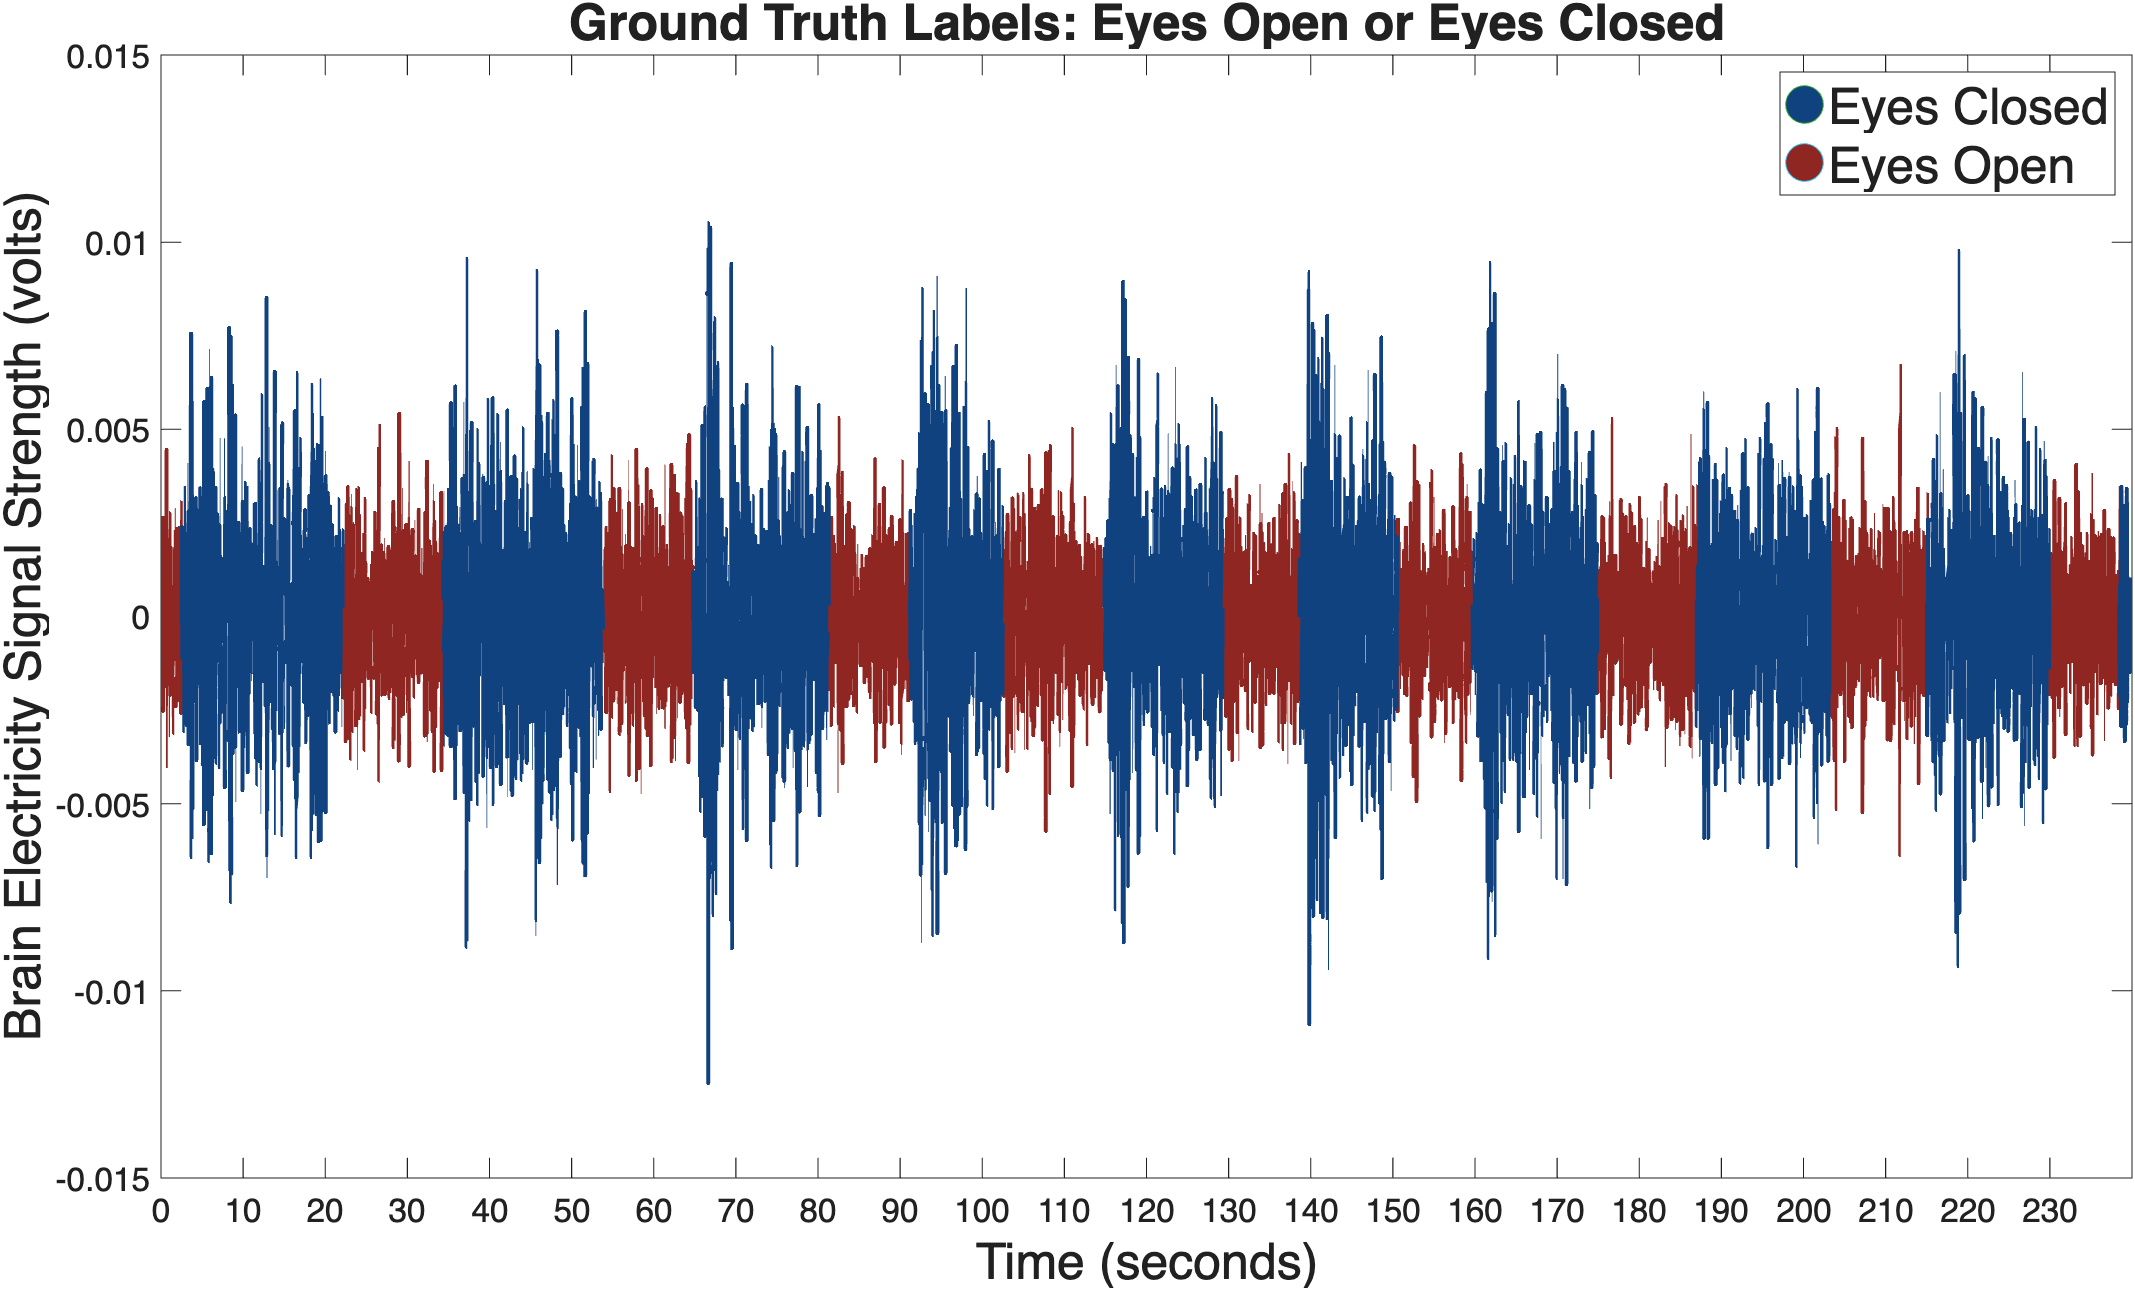

In this next graph, you'll again see the same test data that you hand-labeled. But this time, it's color coded according to predictions the computer program made.

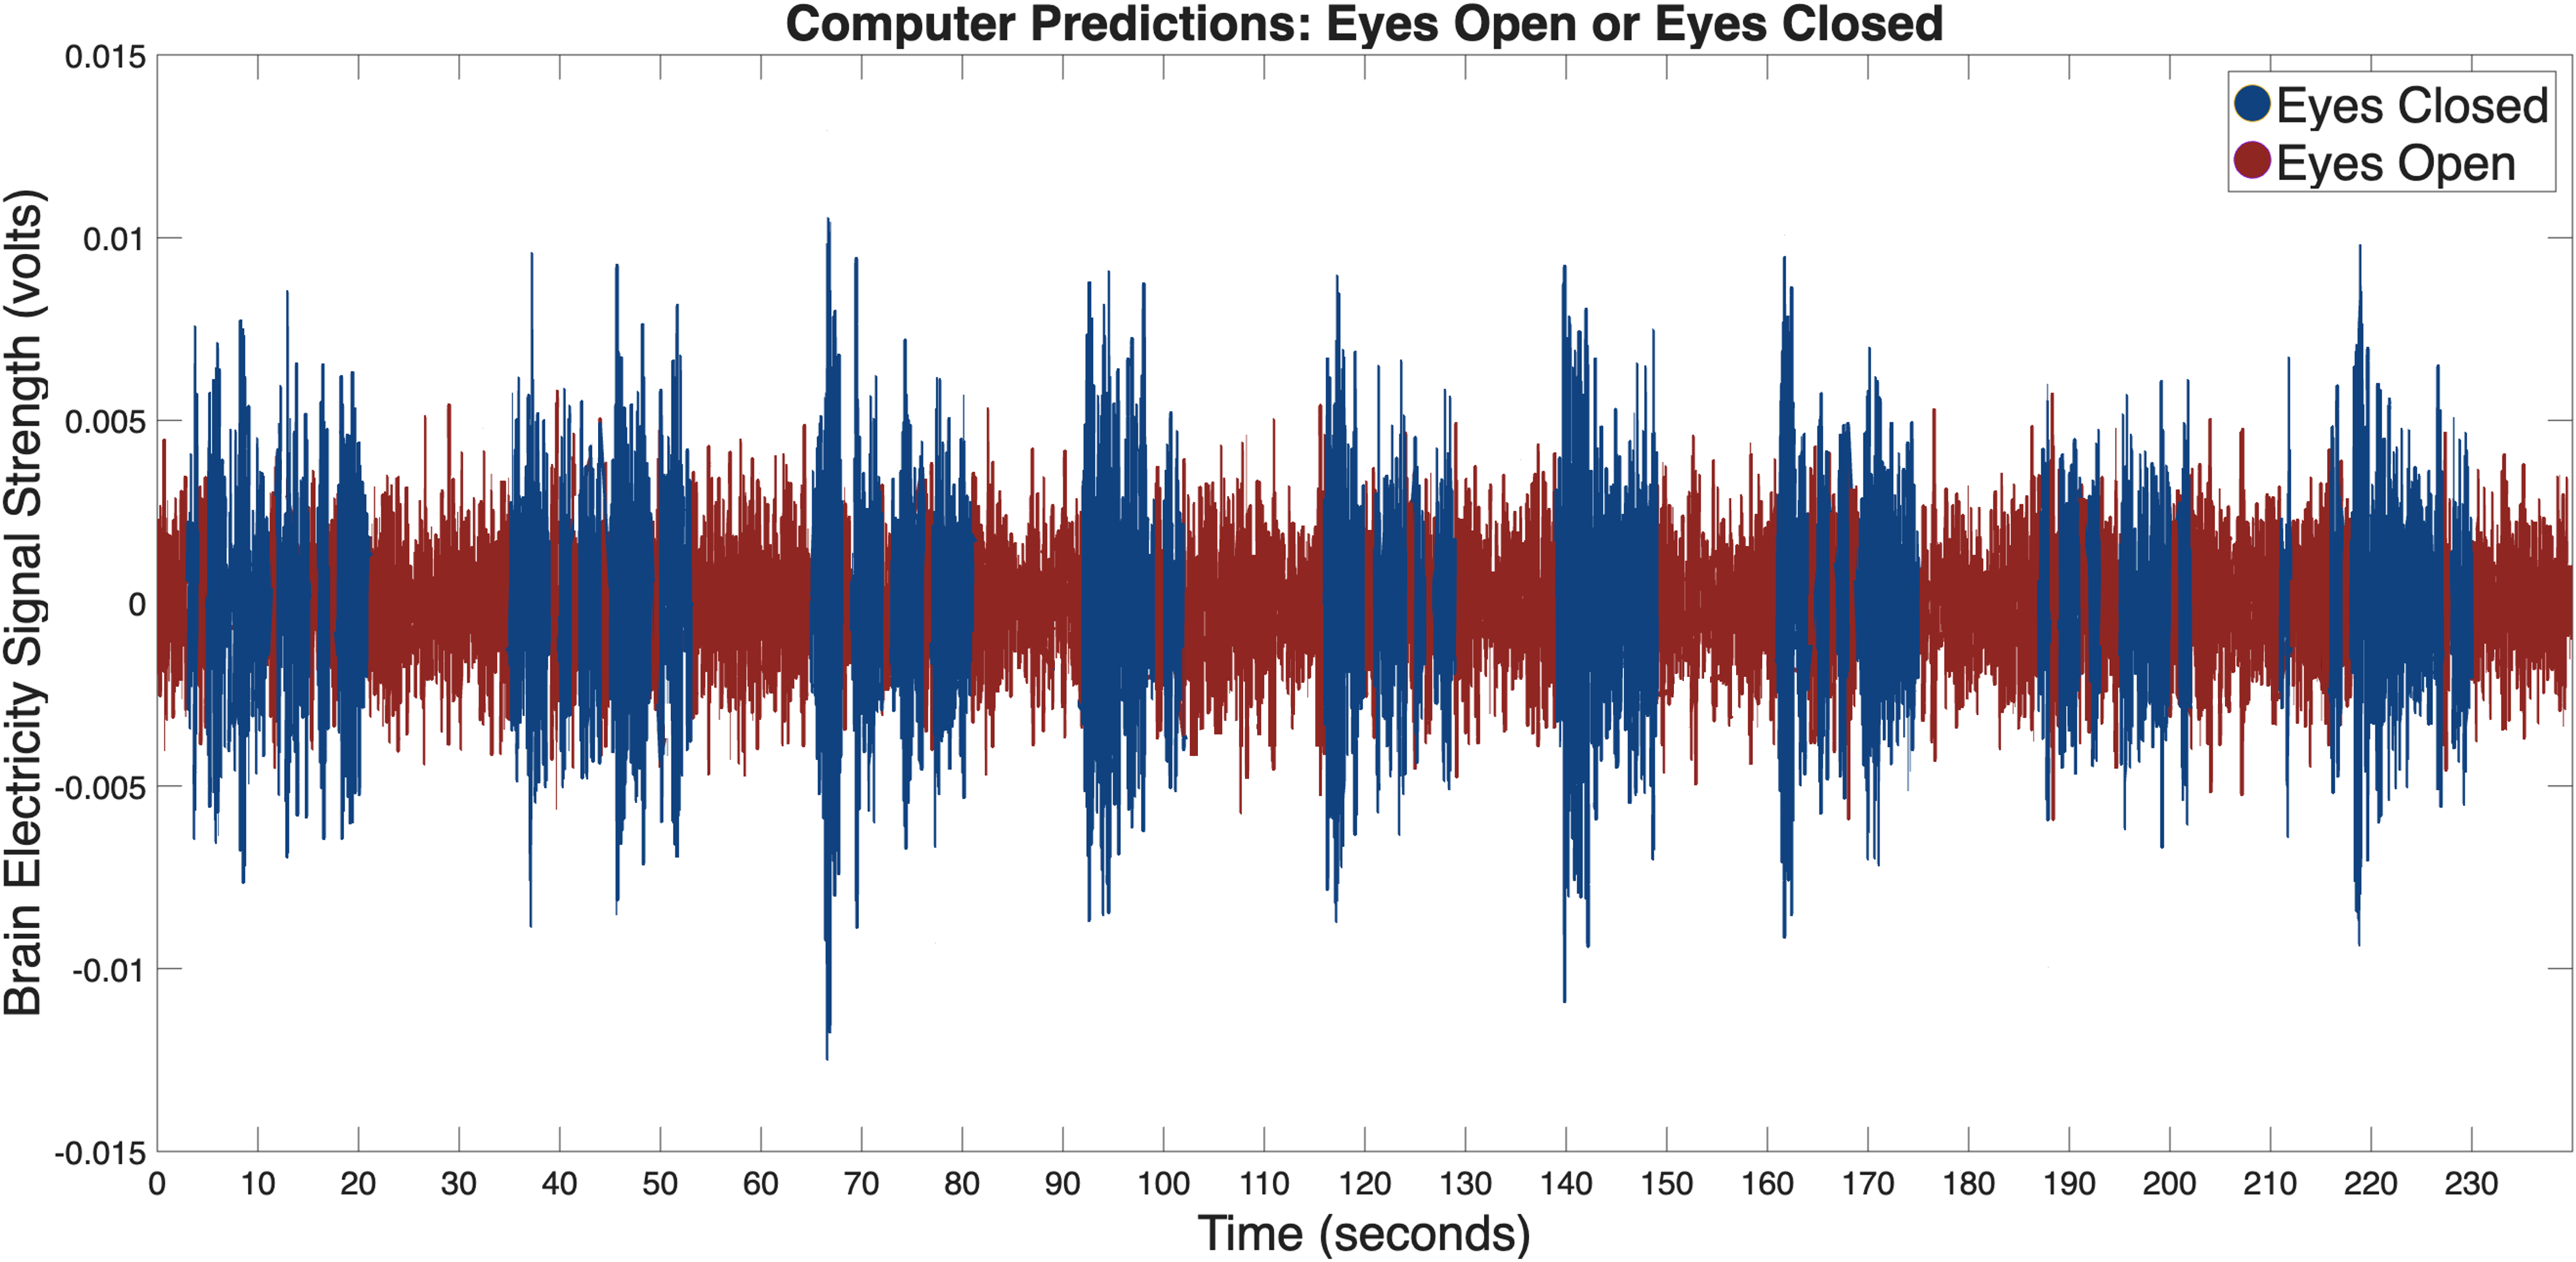

Compare the computer predictions to your hand-labeled data and to the ground truth labels and answer the following discussion questions with your group:

- Were your labels more like the ground truth or more like the computer predictions? Did you do better than the computer at labeling the data accurately?

- Why do you think the computer predictions were different from the ground truth and from your hand-made labels? Are the differences surprising? Why or why not?

- How does this make you think about using computers to automate tasks? What are the pros and cons of accomplishing tasks by hands versus by using a computer?